# SINGLEPREDICTOR

Fit and evaluate a single predictor linear model for fuel economy.

## Load data

load carEcon

## Fit a single-predictor linear model of fuel economy

figure
scatter(carData.EngDisp,carData.FuelEcon,'.')
mdl = fitlm(carTrain.EngDisp,carTrain.FuelEcon);

Add model to plot

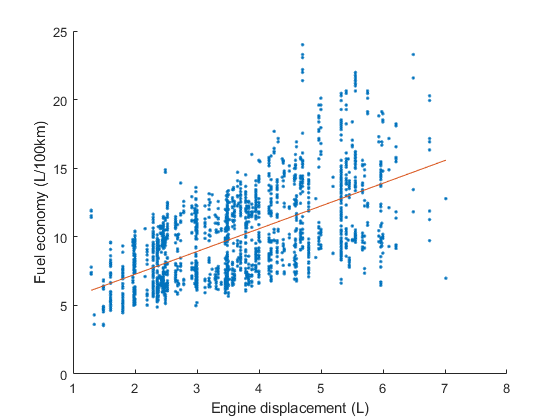

x = [min(carData.EngDisp);max(carData.EngDisp)];
y = predict(mdl,x);
hold on
plot(x,y)
xlabel('Engine displacement (L)')
ylabel('Fuel economy (L/100km)')

## Evaluate model at test predictor values

econpred = predict(mdl,carTest.EngDisp);

## Compare predicted and actual responses

Plot against observation number

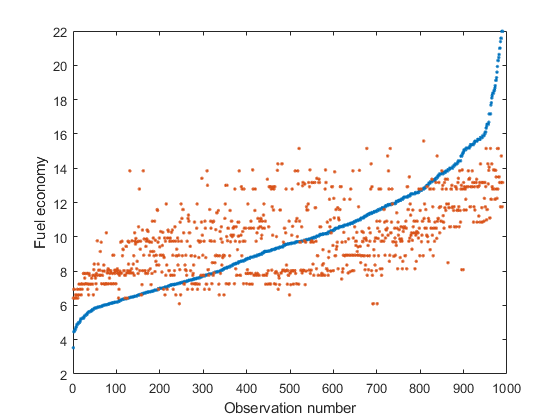

figure
plot(carTest.FuelEcon,'.')
hold on
plot(econpred,'.')
xlabel('Observation number')
ylabel('Fuel economy')

Plot against each other

figure
scatter(carTest.FuelEcon,econpred,'.')
hold on

Add diagonal

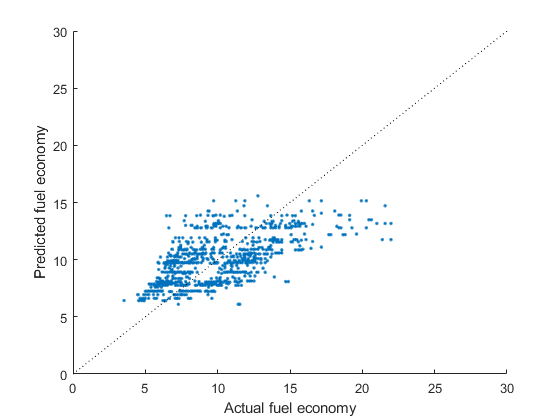

plot([0 30],[0 30],'k:')
xlabel('Actual fuel economy')
ylabel('Predicted fuel economy')

## Plot distribution of errors

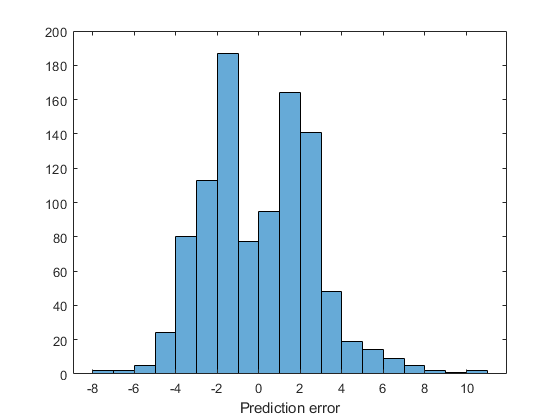

figure
err = carTest.FuelEcon - econpred;
histogram(err)
xlabel('Prediction error')

MSE = mean(err.^2)

MSE = 6.7805

## Plot distribution of percentage errors

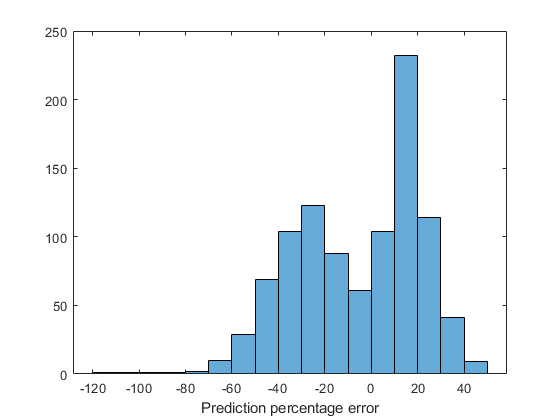

figure
percerr = 100*err./carTest.FuelEcon;
histogram(percerr)
xlabel('Prediction percentage error')

MAPE = mean(abs(percerr))

MAPE = 23.1000